# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 20-Sep-2021 21:59:39

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 8);

% Specify sheet and range
opts.Sheet = "Лист1";
opts.DataRange = "A1:H7";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
lab334 = readtable("C:\физика\labs\2_year\3_term\lab334.xlsx", opts, "UseExcel", false)

lab334 = 7×8 table
    VarName1    VarName2    VarName3    VarName4    VarName5    VarName6    VarName7    VarName8
    ________    ________    ________    ________    ________    ________    ________    ________

       51          75          86         101         123         140         157         172   
      108         143         181         219         251         293         329         356   
      158         214         266         322         373         429         482         535   
      205         275         347         379         483         552         632         693   
      240         322         402         485         568         648         731         808   
      263         356        

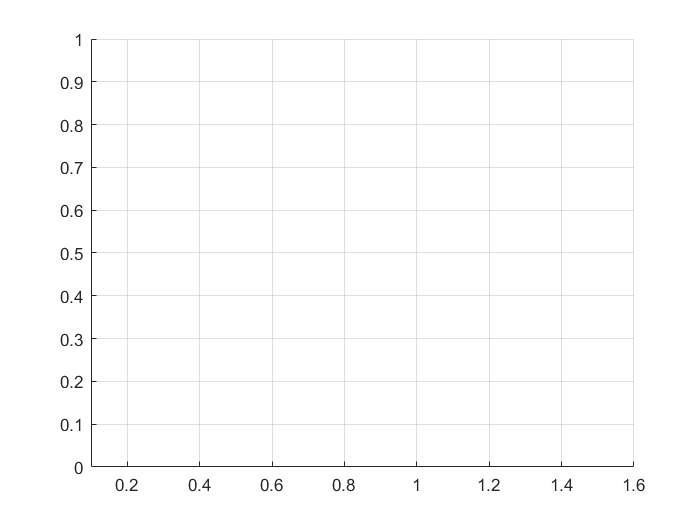

hold on
grid on

A = importdata("lab334.xlsx")

A = struct with fields:
        data: []
    textdata: {}


x(:,1) = date[:,1]
y = [0.2 0.4 0.6 0.8 1.0 1.2 1.4]
xlim([0.1;1.6])
coeff_1 = polyfit(x,y, 2)
y1 = 0;
xi = min(0):0.1:max(1.6)
for k=0:2
    y1 = y1 + coeff_1(2-k+1) * xi.^k;
end
gr_1 = plot(xi, y1); 

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

Unrecognized function or variable 'date'.